load("monkeydata_training.mat");


% trial data contains 100 trials, 8 reaching angles, and
% in each trial theres trains of spikes of 98 neurons and hand position
% during the 672 ms with each time step of 1 ms

% need to estimate the hand position and the hand angle

%cannot use toolbox for submission

% need to see distribution of spikes correlation with hand position

num_trial= length(trial);
num_angle= size(trial,2);
num_neurons= size(trial(1,1).spikes,1);
angle_vector= [30, 70, 110, 150, 190, 230, 310, 350];


figure("Position",[500 558 800 750], 'Name', 'activity of all 98 neurons for each angle');
i_angle=6;
for i_trial= 10:10:80
    ax= subplot(8,1,i_trial/10);
    time= length(trial(i_trial,i_angle).spikes(1,:));
    time_vector= linspace(1, time, time);
    
    for i_neurons= 1:num_neurons
        spikes= trial(i_trial,i_angle).spikes(i_neurons,:);
        plot(time_vector, i_neurons*spikes, '.', 'color', 'k');
        hold on;
    end
    hold off;
    xlabel('Time (ms)');
    ylabel('trial');
%     title("Raster plot for trial 1 of angle "+ angle_vector(i_angle));
title("Raster plot for all neurons in trial "+ i_trial + " for angle "+ angle_vector(i_angle));
end

figure("Position", [500 558 800 750], 'Name', 'Activity of a single neurons for all trial for each angle');
neuron_sel= 1;
for i_angle= 1:num_angle
    subplot(num_angle,1, i_angle);
    hold on;
    for i_trial= 1:num_trial
        time= length(trial(i_trial, i_angle).spikes(neuron_sel,:));
        time_vector= linspace(1, time, time);

        spikes= trial(i_trial, i_angle).spikes(neuron_sel,:);
        plot(time_vector, i_trial*spikes, '.', 'color', 'k');
    end
    xlabel('Time (ms)');
    ylabel('trial');
    title("Angle "+ angle_vector(i_angle));
end
sgtitle("Activity of Neuron "+ neuron_sel);


figure("Position", [500 558 800 750], 'Name', 'Activity of a single neurons for each trial for all angles');
neuron_sel= 1;
for i_trial= 10:10:80
    subplot(num_angle,1, i_trial/10);
    hold on;
    for i_angle= 1:num_angle
        time= length(trial(i_trial, i_angle).spikes(neuron_sel,:));
        time_vector= linspace(1, time, time);

        spikes= trial(i_trial, i_angle).spikes(neuron_sel,:);
        plot(time_vector, i_angle*spikes, '.', 'color', 'k');
    end
    xlabel('Time (ms)');
    ylabel('trial');
%     title("Trial "+ angle_vector(i_angle));
title("Trial "+ i_trial);
end
sgtitle("Activity of Neuron "+ neuron_sel);


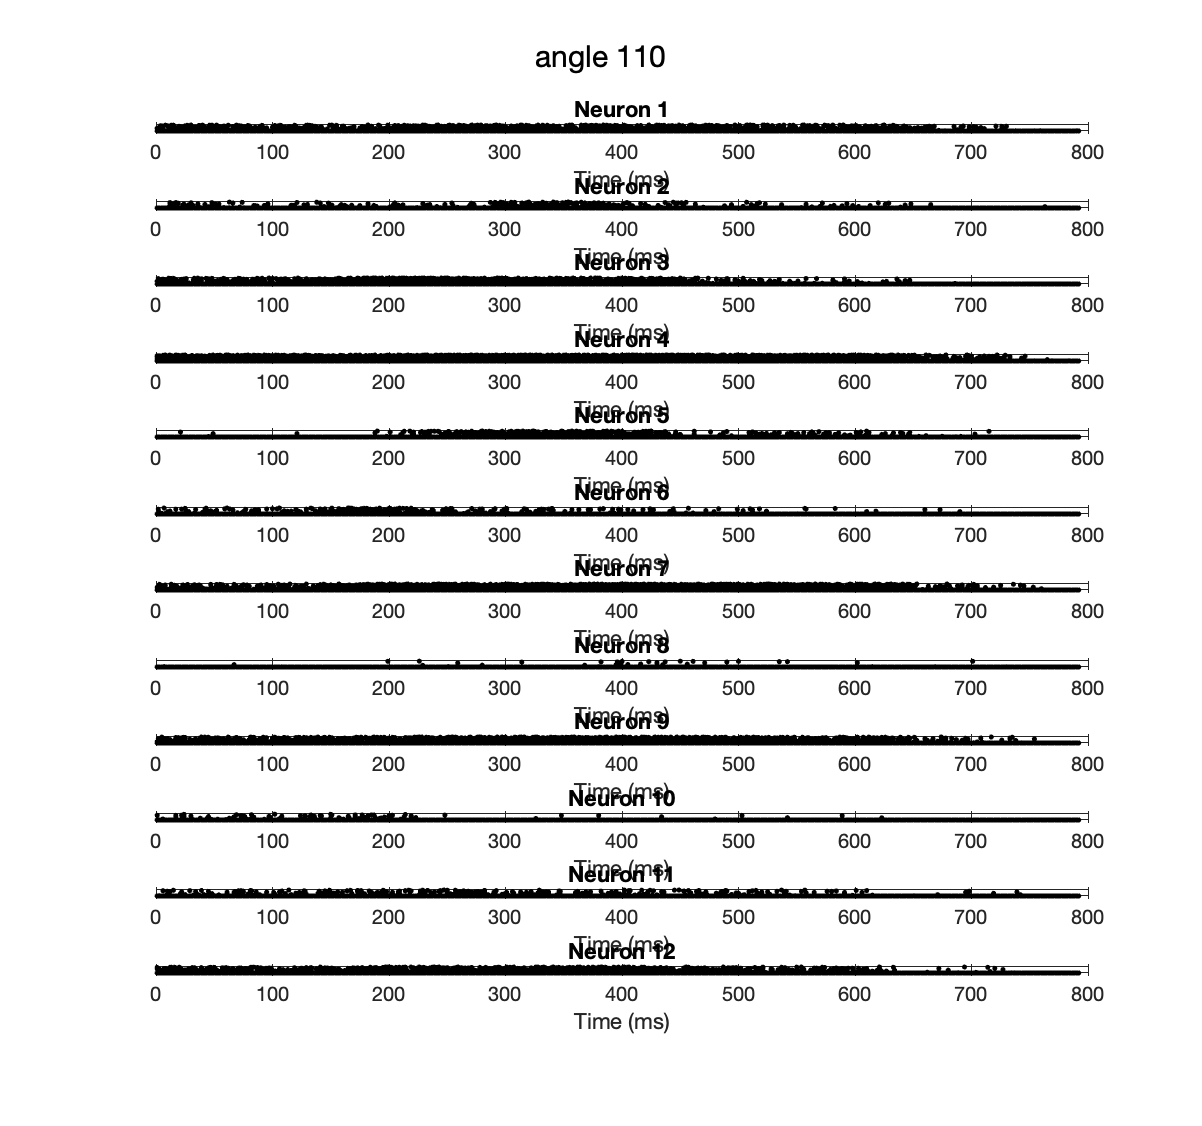

figure("Position", [500 558 800 750], 'Name', 'Activity of a single neurons for one angle for all trials');
i_angle= 3;
for neuron_sel= 1:12
    subplot(12,1, neuron_sel);
    for i_trial= 1:num_trial
        time= length(trial(i_trial, i_angle).spikes(neuron_sel,:));
        time_vector= linspace(1, time, time);

        spikes= trial(i_trial, i_angle).spikes(neuron_sel,:);
        plot(time_vector, i_trial*spikes, '.', 'color', 'k');
        hold on;
    end
    hold off;
    xlabel('Time (ms)');
    ylabel('trial');
%     title("Trial "+ angle_vector(i_angle));
title("Neuron "+ neuron_sel);
end
sgtitle("angle "+ angle_vector(i_angle));

PSTH

Returns the trial averaged firing rate of neuron

- sum each neuron across trials for one angle

len_vect= size(100); %length vector for each angle
neuron_sel=60;
figure('Position',[200 558 1200 750]);
for angle= 1:num_angle
    for i_trial= 1:num_trial
      len_vect(i_trial)= length(trial(i_trial, angle).spikes(neuron_sel,:));
    end
    min_len= min(len_vect);
    ind_spike= zeros(num_trial, min_len);
    neuron_av_rate= zeros(num_neurons, min_len);
    for neuron= 1:num_neurons
        for i_trial= 1:num_trial
            ind_spike(i_trial,:)= trial(i_trial, angle).spikes(neuron,1:min_len);
        end
        neuron_av_rate(neuron,:)= 1000*mean(ind_spike);
    end

    subplot(8,1,angle);
    % bar(linspace(1,min_len, min_len), neuron_av_rate(1,:))
    % title('PSTH before smoothing');
    % xlabel('Time(ms)');
    % ylabel('Average firing rate');
    % subplot(2,1,2);
    bar(linspace(1,min_len,min_len), smooth(neuron_av_rate(neuron_sel,:)));
    title("PSTH of angle "+ angle_vector(angle));
    xlabel('Time(ms)');
    ylabel('Average firing rate (Hz)');
end
    sgtitle("PSTH of Neuron "+ neuron_sel)

Plots of hand positions

- thought outcome: train algorithm to estimate hand positions (X,Y) 

- can use hand position (X,Y) to calculate reaching angle

- finding: hand started moving from mid 300ms onwards

angle= 7;
figure('Position',[200 558 1200 750]);
for i_trial= 10:10:100
    subplot(10,1,(i_trial/10));
    xlabel('distance');
    len= length(trial(i_trial, angle).handPos(1,:));
    scatter(linspace(1, len, len), trial(i_trial, angle).handPos(1, :), 'black');
    hold on;
    scatter(linspace(1, len, len), trial(i_trial, angle).handPos(2, :),'diamond', 'blue');
    title("trial "+ i_trial);
end
legend('x-distance', 'y-distance');
sgtitle("Hand Position for angle " + angle_vector(angle));

**Tuning Curve**

Plot average firing rate against orientation

- find the average firing rate of spikes **across trials and over time** for various orientations

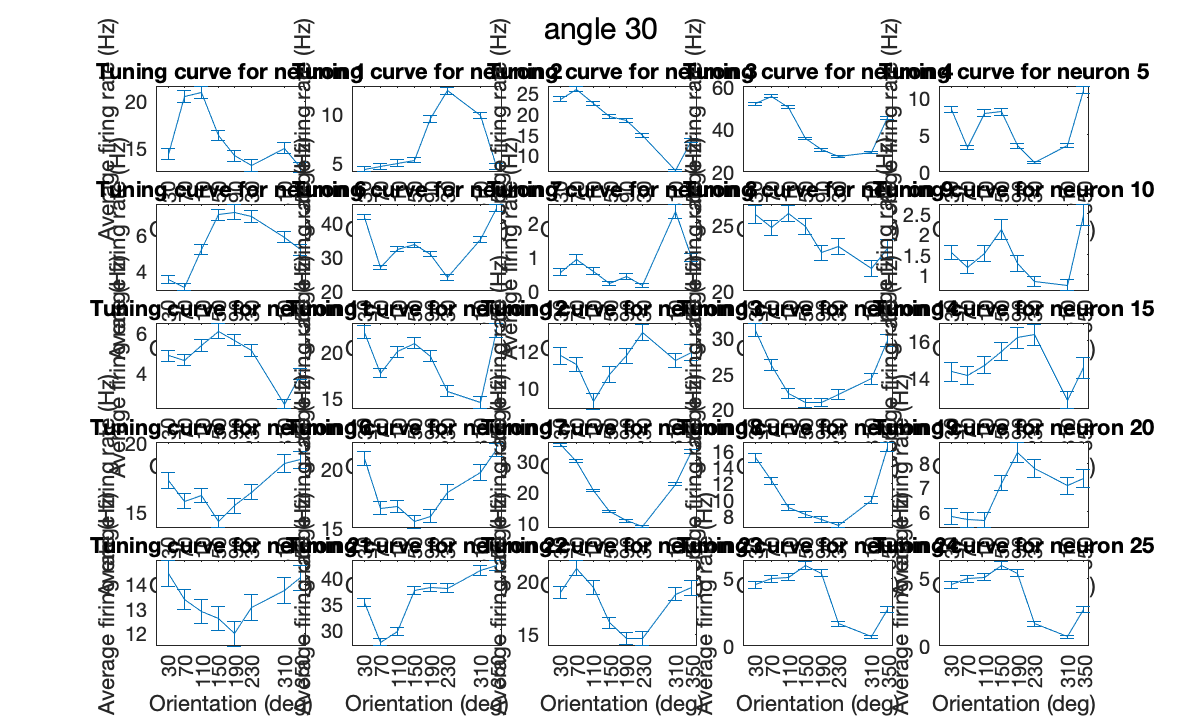

tuning_curve_vect= zeros(1,8);
min_vect=zeros(100, 8);
for angle= 1: num_angle
    for i_trial= 1:num_trial
        min_vect(i_trial, angle)= length(trial(i_trial,angle).spikes(1,:));
    end
end
min_time_angle= min(min_vect);
figure('Position',[0 558 2000 1200]);
err= zeros(1,num_angle);
preferred_directions= zeros(num_neurons,1);
i=0;
for neuron_sel= 1:25
    i= i+1;
    for angle= 1:num_angle
        total_spikes= zeros(num_trial,min_time_angle(angle));
        total_spikes_2=zeros(1, min_time_angle(angle));
        for i_trial= 1:num_trial
            total_spikes(i_trial, :)= trial(i_trial,angle).spikes(neuron_sel, 1:min_time_angle(angle));
        end
        av_time= mean(total_spikes,2);
        err(angle)= 100*std(av_time);
        tuning_curve_vect(angle)= 1000*mean(total_spikes, 'all');
    end
      [~, argmax]=max(tuning_curve_vect);
      preferred_directions(neuron_sel)= angle_vector(argmax);
      
    subplot(5,5,i)
    errorbar(angle_vector, tuning_curve_vect, err);
    xlim([0 360]);
    xticks(angle_vector);
    xlabel('Orientation (deg)');
    ylabel('Average firing rate (Hz)');
    title("Tuning curve for neuron "+ neuron_sel);
end

% ylim([0 0.3]);

**Population vector algorithm**

- Collect firing rates: Record the firing rates of a population of neurons as a subject performs a movement. Each neuron's firing rate can be represented as a vector, with one dimension for each direction or movement variable of interest (e.g., x, y, and z position).

- Normalize firing rates: Normalize each neuron's firing rates by dividing them by the maximum firing rate for that neuron across all directions. This ensures that each neuron's contribution to the population vector is weighted equally, regardless of its overall firing rate.

- Compute the population vector: Compute the population vector by taking the weighted sum of the normalized firing rate vectors, with each neuron's contribution weighted by the cosine of its preferred direction. The population vector represents the direction of movement that is most strongly represented by the population of neurons.

- Decode movement: Use the magnitude and direction of the population vector to decode the movement. For example, the direction of the population vector can be used to decode the direction of a reaching movement, while the magnitude of the population vector can be used to decode the force of a muscle contraction.

Question for GTA: perform the population vector algorithm on what data (the spikes of one trial)? how to obtain the preferred direction of multineuron units (is it just the max firing rate amogn all regardless of the number of peaks)?

pop_vector(50, 3, trial, preferred_directions, angle_vector)

**Data Preprocessing ;**

Separate X train for 

Xtrain= 100*8 of 98 spikes trains. cell Size= (100*8, 98) with each cell containing spike trains

ytrain= 100*8 of 2 (x, y) hand positions. cell Size=(100*8, 2)

[xtrain, ytrain]= get_data(trial);

function pop_angle= pop_vector(i_trial, angle, trial, preferred_directions, angle_vector)
    thisTrial= trial(i_trial, angle);
    num_neurons= size(thisTrial.spikes,1);
    unit_vector= zeros(num_neurons, 2);
    av_rate= zeros(num_neurons, 1);
    cos_directions=cos(deg2rad(mod(preferred_directions-angle_vector(angle),360)-180));
%     cos_directions=cos(deg2rad(mod(preferred_directions,360)-180)); 
    for neuron_sel=1:num_neurons
        av_rate(neuron_sel)= mean(thisTrial.spikes(neuron_sel,:)); %get the average firing rate for one neuron 
        pref_angle= deg2rad(preferred_directions(neuron_sel)); 
        unit_vector(neuron_sel,:)= [cos(pref_angle), sin(pref_angle)]; %compute the unit vector of the preferred direction as obtained in the tuning curve 
    end
    normalized_rate= av_rate/max(av_rate);
    weightage= normalized_rate.*cos_directions;
    pop_vect= sum(weightage.*unit_vector);
    pop_angle= atand(pop_vect(2)/pop_vect(1)); % angle relative to movement direction 
end

function [spikes, handPos]= get_data(trial)
    num_trial= length(trial);
    num_angle= size(trial,2);
    new_trial= trial(:);
    num_neurons= height(trial(1).spikes);
    %construct cells to hold data
    spikes= cell(num_trial*num_angle, num_neurons);
    handPos= cell(num_trial*num_angle, 2);
    %flatten trial array 
    for i= 1:num_trial*num_angle
        for j= 1:num_neurons
            spikes{i,j}= new_trial(i).spikes(j,:);  
        end
        handPos{i,1}= new_trial(i).handPos(1,:);
        handPos{i,2}= new_trial(i).handPos(2,:);
    end   
        
end

%will probably need to concatenate all the spikes data from each neuron and
% its respective hand position